clc; clear;

Enter Time axis as [start:step:stop]:

t = -15:0.1:20;
[x, str] = AperiodicSignal(AxisType.t,t, [-0.5 0.2], [zeros(size(t)); 2*ones(size(t)); zeros(size(t))]);
fprintf("%s",compose("signal shape/waveform sections :\n%s", str));

signal shape/waveform sections :
  t<-0.5 , section_1
  -0.5<=t<0.2 , section_2
  t=>0.2 , section_3


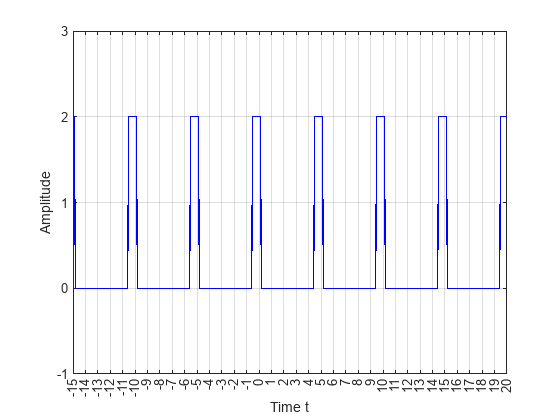

per_signal = PeriodicSignal(t,x,5);
Draw(AxisType.t,t, per_signal)